%% Generate default treeshrew optics
tOI = oiTreeShrewCreate();

## Generate default human optics

hOI = oiCreate('wvf human')

hOI = struct with fields:
           type: 'opticalimage'
           name: 'human-WVF'
           data: [1×1 struct]
         optics: [1×1 struct]
       diffuser: [1×1 struct]
    consistency: 1


## Generate human and treeshrew L-cone only mosaics

spatialLMSdensities = [0 1 0 0]; % L-only mosaic
fovDegs = 0.3*[1 1];
% Human cones: 2 micron separation
coneSeparationMicrons = 2.0;
cHuman = coneMosaicHex(7, ...
    'spatialDensity', spatialLMSdensities, ...
    'customLambda', coneSeparationMicrons, ...
    'customInnerSegmentDiameter', coneSeparationMicrons, ...
    'integrationTime', 5/1000, ...
    'fovDegs', fovDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 0
Scones after making an S-cone free central patch: 0 (added Lcones:0, added Mcones:0)


% Treeshrew mosaic
% Human cones: 6 micron separation
coneSeparationMicrons = 6.0;
cTreeShrew = coneMosaicTreeShrewCreate(tOI.optics.micronsPerDegree, ...
    'customLambda', coneSeparationMicrons, ...
    'customInnerSegmentDiameter', coneSeparationMicrons, ...
    'lConeDensity', spatialLMSdensities(2), ...
    'integrationTime', 5/1000, ...
    'fovDegs', fovDegs);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 0
Scones after making an S-cone free central patch: 0 (added Lcones:0, added Mcones:0)
Will not adjust the minimum S-cone separation
.

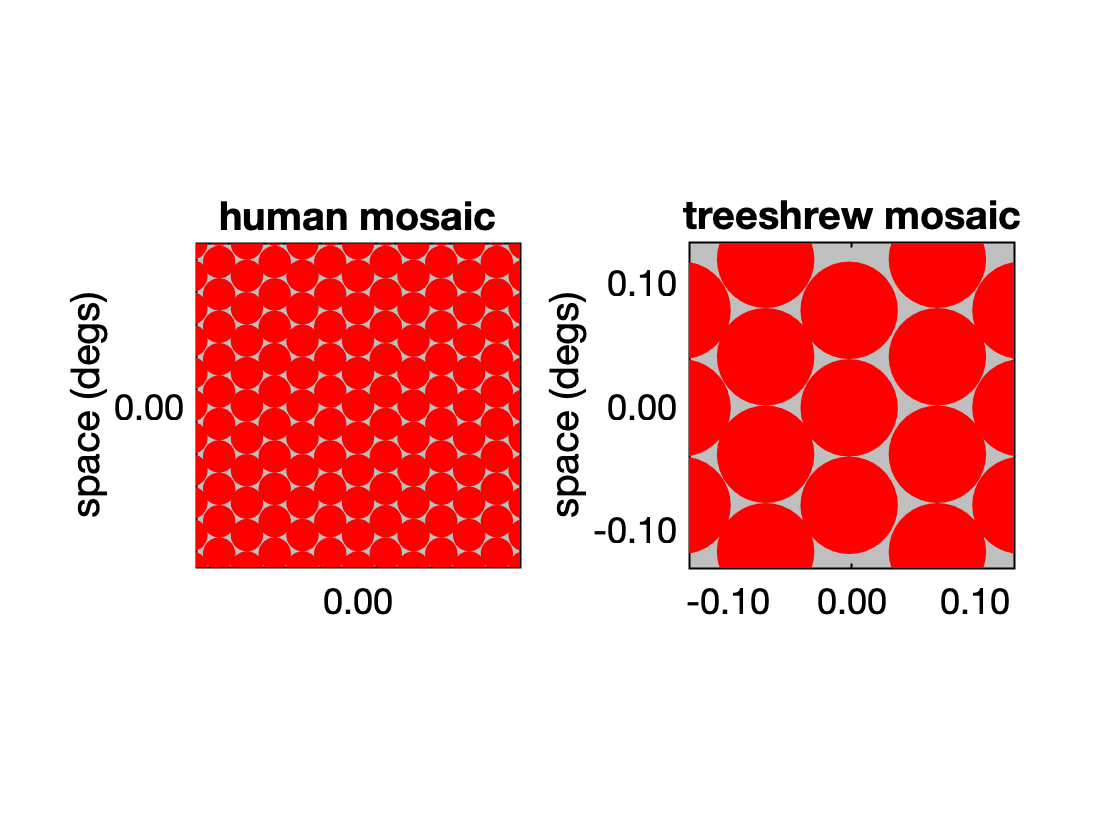

% Plot mosaics
figure(); clf;
subplot(1,2,1);
cHuman.visualizeGrid(...
    'axesHandle', gca, ...
    'displayVisualDegs', true);
% 50 microns across
visualizedMicronsAcross = 20*[-0.5 0.5]*1e-6;
set(gca, 'XLim', visualizedMicronsAcross, 'YLim', visualizedMicronsAcross);
title('human mosaic')

subplot(1,2,2);
cTreeShrew.visualizeGrid(...
    'axesHandle', gca, ...
    'displayVisualDegs', true);
% 50 microns across
set(gca, 'XLim', visualizedMicronsAcross, 'YLim', visualizedMicronsAcross)
title('treeshrew mosaic')

testScene = sceneCreate('uniformEqualPhoton');
sceneGet(testScene, 'mean lum')

ans = 100.0000

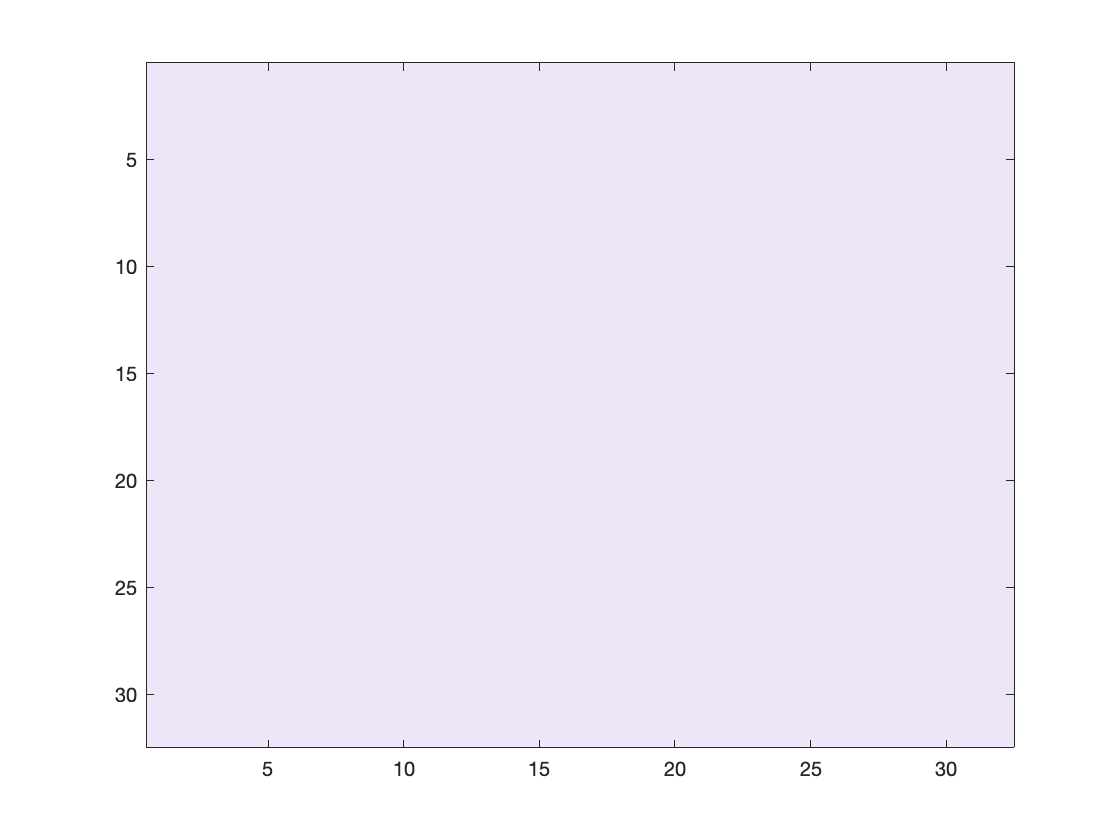

figure()
image(sceneGet(testScene, 'rgb image'))

%% Compute the retinal image
tOI = oiCompute(tOI, testScene);
hOI = oiCompute(hOI, testScene);
% Compute mosaic responses
nTrialsNum = 3;
emPath = zeros(nTrialsNum, 1, 2);

% Compute human mosaic excitation responses to treeshrew optical image
humanConeExcitationsTreeShrewOI = cHuman.compute(tOI, 'emPath', emPath);
% Compute human mosaic excitation responses to human optical image
humanConeExcitationsHumanOI = cHuman.compute(hOI, 'emPath', emPath);
% Compute treeshrew mosaic excitation responses to treeshrew optical image
treeShrewConeExcitationsTreeShrewOI = cTreeShrew.compute(tOI, 'emPath', emPath);

idx = find(cHuman.pattern == 2);
numel(idx)

ans = 2269

humanConeExcitationsTreeShrewOI  = reshape(humanConeExcitationsTreeShrewOI , [nTrialsNum numel(cHuman.pattern)]);
humanConeExcitationsHumanOI  = reshape(humanConeExcitationsHumanOI , [nTrialsNum numel(cHuman.pattern)]);
meanHumanLconeResponseTreeShrewOI = mean(mean(humanConeExcitationsTreeShrewOI (:,idx)))

meanHumanLconeResponseTreeShrewOI = 1.6424e+03

meanHumanLconeResponseHumanOI = mean(mean(humanConeExcitationsHumanOI(:,idx)))

meanHumanLconeResponseHumanOI = 62.5421


idx = find(cTreeShrew.pattern == 2);
numel(idx)

ans = 17

treeShrewConeExcitationsTreeShrewOITreeShrewOI = reshape(treeShrewConeExcitations, [nTrialsNum numel(cTreeShrew.pattern)]);
size(treeShrewConeExcitations)

ans =            3        7056


meanTreeShrewLconeResponse = mean(mean(treeShrewConeExcitationsTreeShrewOI(:,idx)))

meanTreeShrewLconeResponse = 1.6905e+03

w = cHuman.wave;
hPigment = cHuman.pigment

hPigment =   photoPigment with properties:

        opticalDensity: [3×1 double]
        peakEfficiency: [3×1 double]
                 width: 1.7725e-06
                height: 1.7725e-06
               pdWidth: 1.7725e-06
              pdHeight: 1.7725e-06
                  wave: [31×1 double]
            absorbance: [31×3 double]
           absorptance: [31×3 double]
    quantaFundamentals: [31×3 double]
    energyFundamentals: [31×3 double]
                  area: 3.1416e-12
                pdArea: 3.1416e-12
              gapWidth: 0
             gapHeight: 0



micronsPerDegree = 80

micronsPerDegree = 80

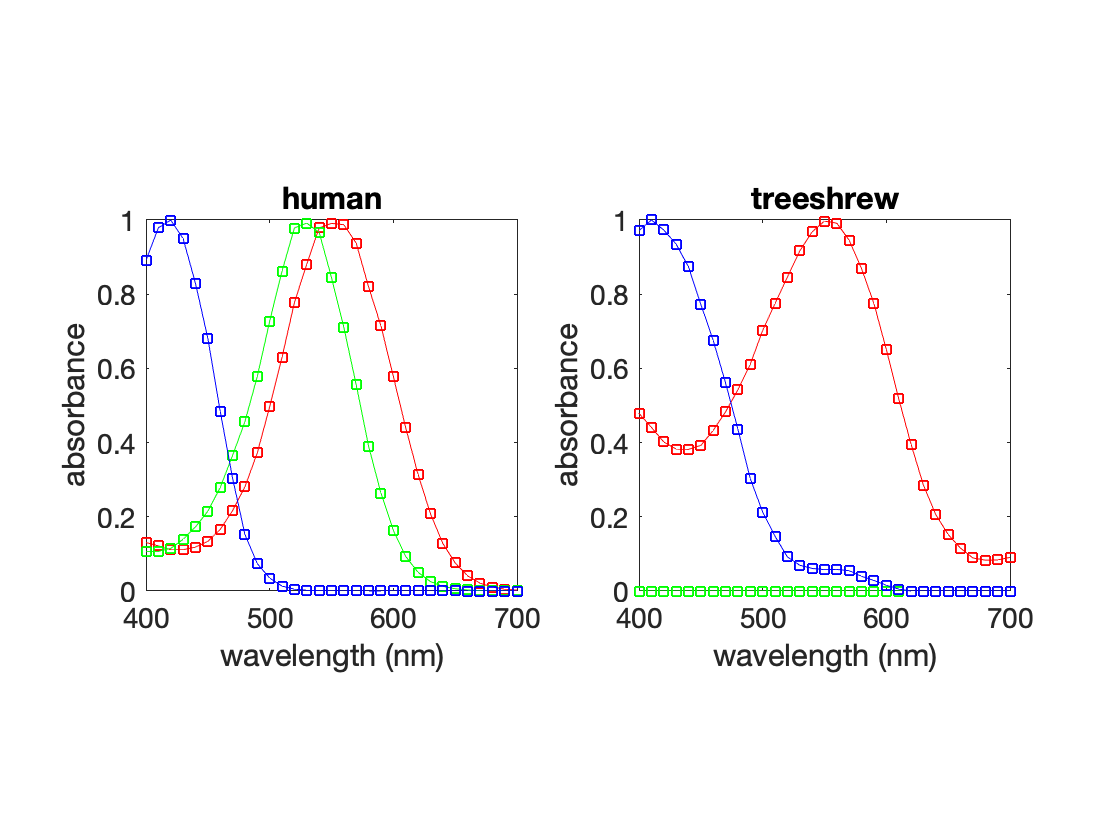

wT = cTreeShrew.wave;
tPigment = cTreeShrew.pigment;

% Retrieve the absorbance spectra. 
% Note that these are normalized to peak value of 1.
figure();
subplot(1,2,1)
humanAbsorbance = hPigment.absorbance;
plotActionSpectra(w, humanAbsorbance, 'absorbance', 'human')
subplot(1,2,2)
treeShrewAbsorbance = tPigment.absorbance;
plotActionSpectra(w, treeShrewAbsorbance, 'absorbance', 'treeshrew')

% Compute the axial absorbance, absorbance * axial optical density
axialDensities = hPigment.opticalDensity

axialDensities =     0.5000
    0.5000
    0.4000


humanAxialAbsorbance = humanAbsorbance * diag(axialDensities);
axialDensities = tPigment.opticalDensity

axialDensities =     0.0370
         0
    0.0389


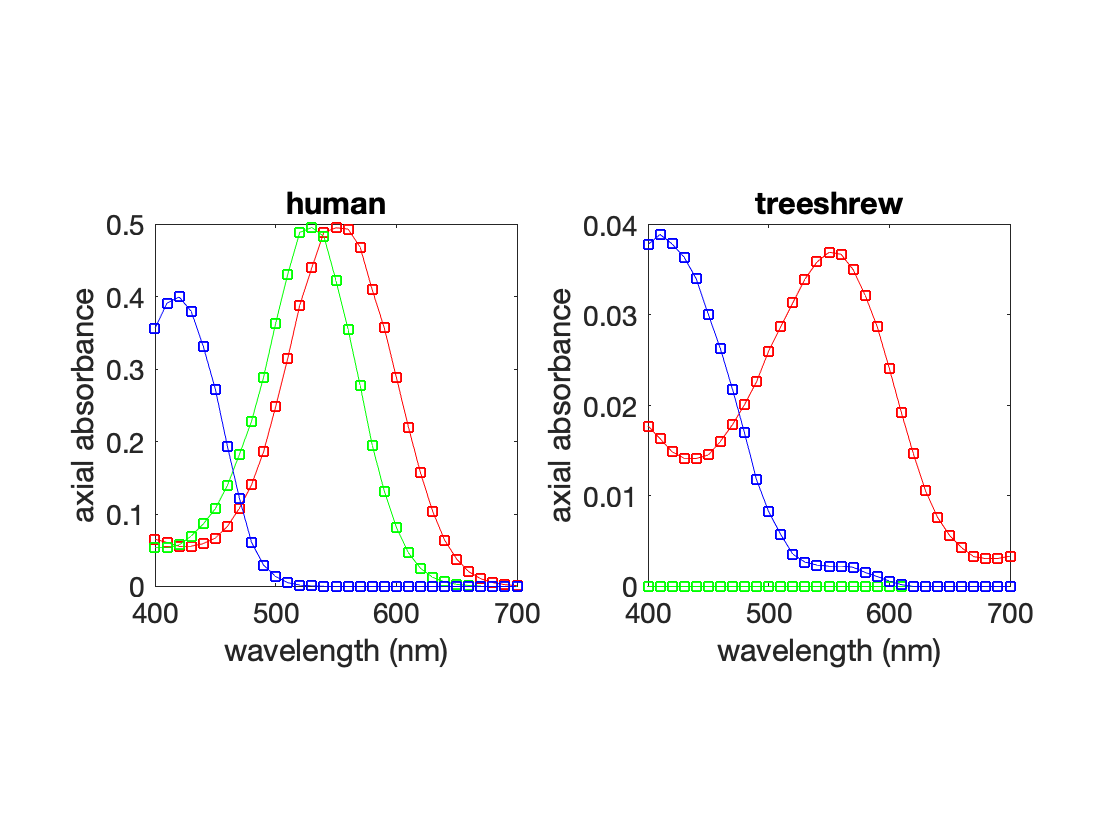

treeShrewAxialAbsorbance = treeShrewAbsorbance * diag(axialDensities);
figure()
subplot(1,2,1)
plotActionSpectra(w, humanAxialAbsorbance, 'axial absorbance', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewAxialAbsorbance, 'axial absorbance', 'treeshrew')

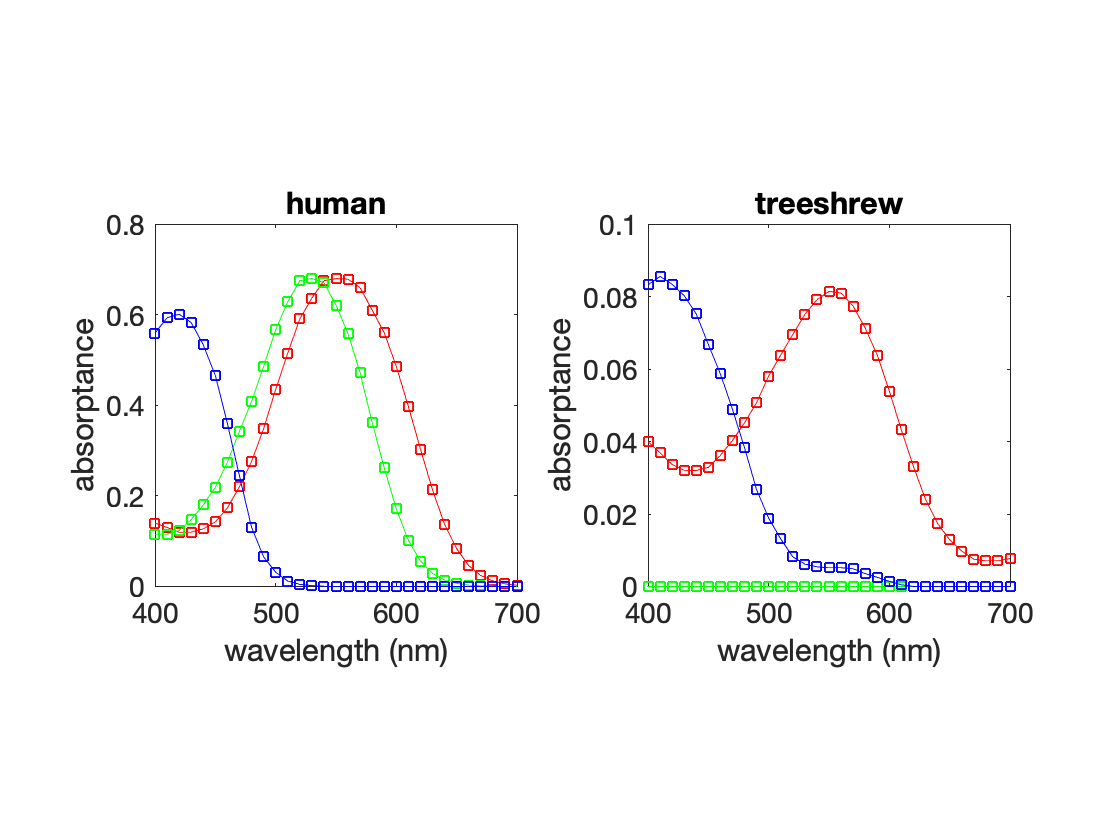


% Compute absorptance, the ratio of absorbed photons
humanAbsorptance = 1 - 10 .^ (-humanAxialAbsorbance);
treeShrewAbsorptance = 1 - 10 .^ (-treeShrewAxialAbsorbance);
figure()
subplot(1,2,1)
plotActionSpectra(w, humanAbsorptance, 'absorptance', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewAbsorptance, 'absorptance', 'treeshrew')

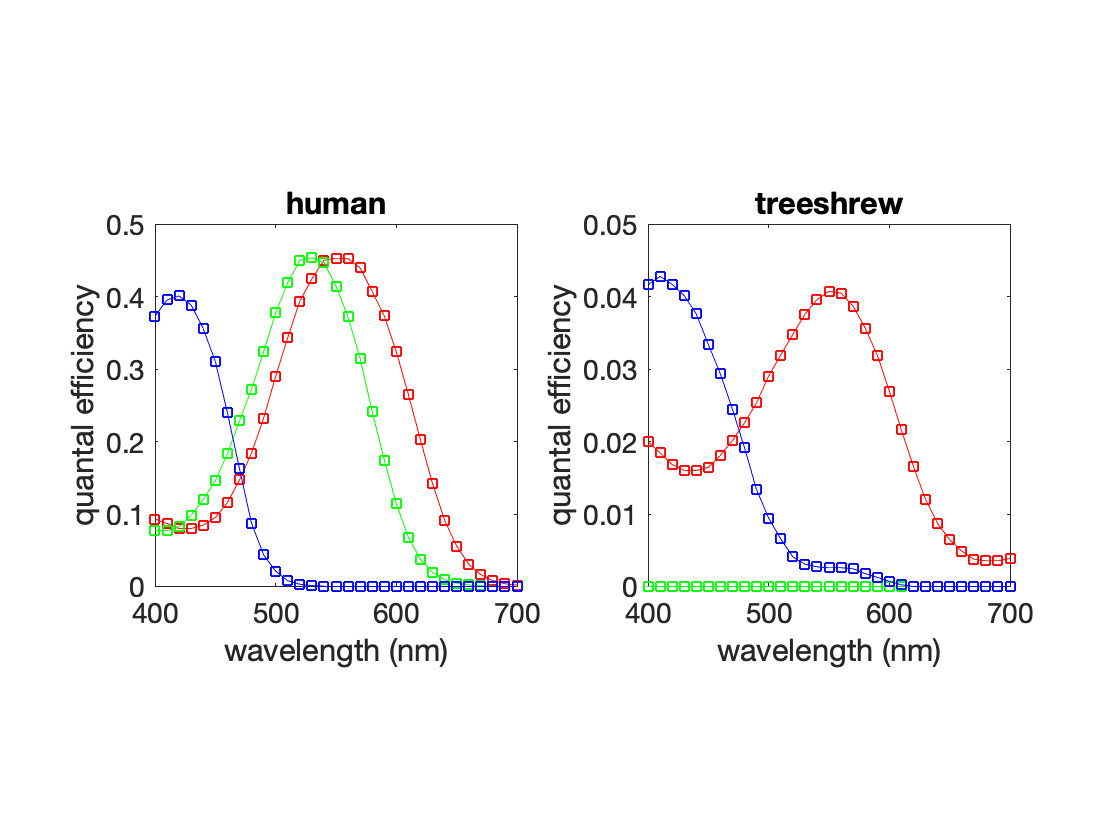

% Compute quantal efficiencies (not accounting for macular/lens pigments)
peakEfficiencies = hPigment.peakEfficiency;
humanQuantalEfficiency = humanAbsorptance * diag(peakEfficiencies);
peakEfficiencies = tPigment.peakEfficiency;
treeShrewQuantalEfficiency = treeShrewAbsorptance * diag(peakEfficiencies);
figure()
subplot(1,2,1)
plotActionSpectra(w, humanQuantalEfficiency, 'quantal efficiency', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewQuantalEfficiency, 'quantal efficiency', 'treeshrew')

% Compute integrated (over cone aperture) quantal efficiency 
innerSegmentArea = hPigment.pdArea*1e12

innerSegmentArea = 3.1416

humanIntegratedQuantalEfficiency = humanQuantalEfficiency * innerSegmentArea;
innerSegmentArea = tPigment.pdArea*1e12

innerSegmentArea = 28.2743

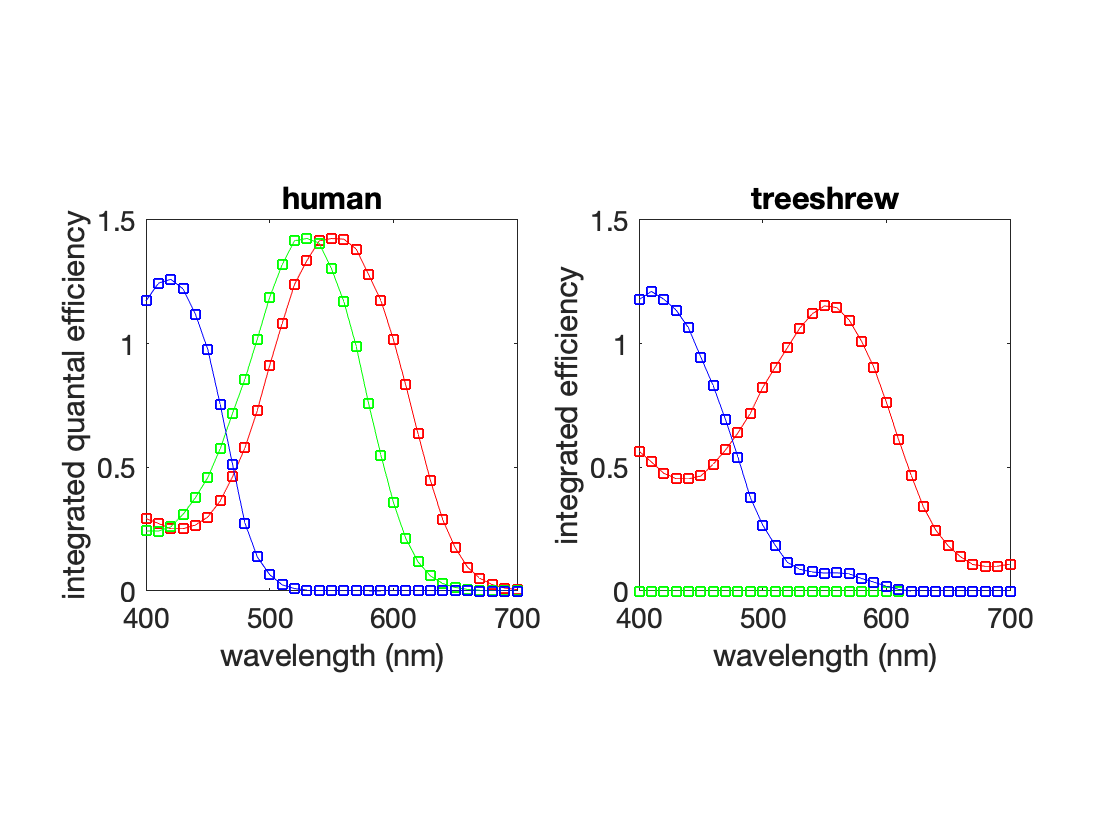

treeShrewIntegratedQuantalEfficiency = treeShrewQuantalEfficiency * innerSegmentArea;
figure()
subplot(1,2,1)
plotActionSpectra(w, humanIntegratedQuantalEfficiency, 'integrated quantal efficiency', 'human')
subplot(1,2,2)
plotActionSpectra(w, treeShrewIntegratedQuantalEfficiency, 'integrated efficiency', 'treeshrew')

function plotActionSpectra(w, a, aName, tName)
    plot(w, a(:,1), 'rs-'); hold on;
    plot(w, a(:,2), 'gs-');
    plot(w, a(:,3), 'bs-');
    axis 'square'
    xlabel('wavelength (nm)')
    ylabel(aName)
    title(tName)
    set(gca, 'FontSize', 14)
end